## **JULIO CESAR GARCIA RIBEIRO                                      RA: 1994484**

#### **ATIVIDADE PRÁTICA 4**

**Sinal original e sinal com adição do ruído:**

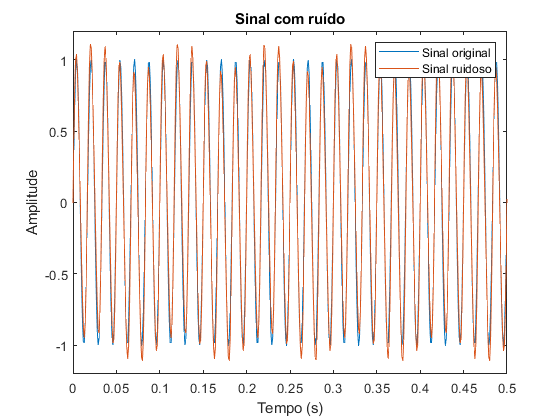

Fs = 1000;
t = 0:1/Fs:1;
signal = sin(120*pi*t);
noise1 = 0.1*sin(20*pi*t);
noise2 = 0.1*sin(240*pi*t);
noisy_signal = signal + noise1 + noise2;

figure;
plot(t, signal); xlim([0, 0.5]); ylim([-1.2, 1.2]);
hold on;
plot(t, noisy_signal); xlim([0, 0.5]); ylim([-1.2, 1.2]);
title('Sinal com ruído'); xlabel('Tempo (s)'); ylabel('Amplitude');
legend('Sinal original', 'Sinal ruidoso');

Comparação no domínio do tempo do sinal original e do sinal adicionado de ruído.

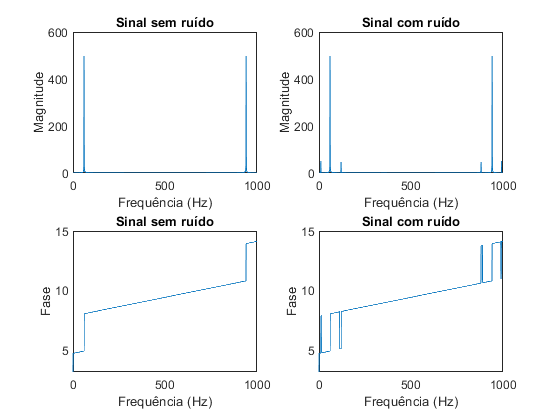

fourier_signal = fft(signal);
fourier_noisy_signal = fft(noisy_signal);
f = linspace(0, Fs, length(signal));

figure;
subplot(2, 2, 1);
plot(f, abs(fourier_signal));
title('Sinal sem ruído'); xlabel('Frequência (Hz)'); ylabel('Magnitude');
subplot(2, 2, 2);
plot(f, abs(fourier_noisy_signal));
title('Sinal com ruído'); xlabel('Frequência (Hz)'); ylabel('Magnitude');
subplot(2, 2, 3);
plot(f, phase(fourier_signal));
title('Sinal sem ruído'); xlabel('Frequência (Hz)'); ylabel('Fase');
subplot(2, 2, 4);
plot(f, phase(fourier_noisy_signal));
title('Sinal com ruído'); xlabel('Frequência (Hz)'); ylabel('Fase');

Comparação do domínio da frequência do sinal original e adicionado de ruído.

**Filtragem das frequencias altas do sinal utilizando 3 métodos:**

Foi desenvolvido 3 filtros, para filtrar a componente de altra frequencia do sinal, com metodologia Butterworth, Chebyshev Tipo 1 e Elliptic. Os sinais filtrados são comparados posteriormente.

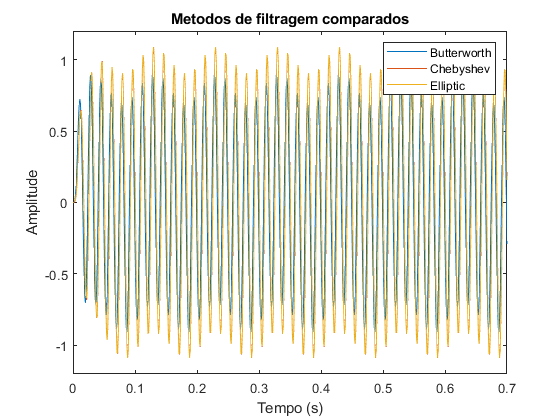

signal_butterworth = filter(Butterworth, noisy_signal);
signal_chebyshev = filter(Chebyshev, noisy_signal);
signal_elliptic = filter(Elliptic, noisy_signal);
fourier_signal_butterworth = fft(signal_butterworth);
fourier_signal_chebyshev = fft(signal_chebyshev);
fourier_signal_elliptic = fft(signal_elliptic);

figure;
plot(t, signal_butterworth); xlim([0, 0.7]); ylim([-1.2, 1.2]);
hold on;
plot(t, signal_chebyshev); xlim([0, 0.7]); ylim([-1.2, 1.2]);
hold on;
plot(t, signal_elliptic); xlim([0, 0.7]); ylim([-1.2, 1.2]);
title('Metodos de filtragem comparados'); xlabel('Tempo (s)'); ylabel('Amplitude');
legend('Butterworth', 'Chebyshev', 'Elliptic');

Comparação no domínio do tempo dos sinais filtrados.

Se percebe grande semelhança nas respostas do silnal com filtro Chebyshev Tipo 1 e Elliptic e um maior atraso em ambos com comparação ao sinal com filtro Butterworth.

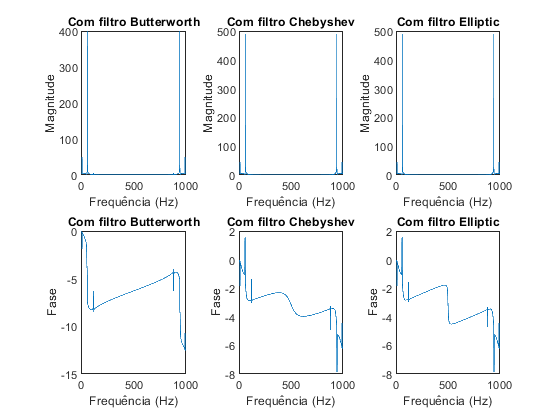

figure;
subplot(2, 3, 1);
plot(f, abs(fourier_signal_butterworth));
title('Com filtro Butterworth'); xlabel('Frequência (Hz)'); ylabel('Magnitude');
subplot(2, 3, 2);
plot(f, abs(fourier_signal_chebyshev));
title('Com filtro Chebyshev'); xlabel('Frequência (Hz)'); ylabel('Magnitude');
subplot(2, 3, 3);
plot(f, abs(fourier_signal_elliptic));
title('Com filtro Elliptic'); xlabel('Frequência (Hz)'); ylabel('Magnitude');
subplot(2, 3, 4);
plot(f, phase(fourier_signal_butterworth));
title('Com filtro Butterworth'); xlabel('Frequência (Hz)'); ylabel('Fase');
subplot(2, 3, 5);
plot(f, phase(fourier_signal_chebyshev));
title('Com filtro Chebyshev'); xlabel('Frequência (Hz)'); ylabel('Fase');
subplot(2, 3, 6);
plot(f, phase(fourier_signal_elliptic));
title('Com filtro Elliptic'); xlabel('Frequência (Hz)'); ylabel('Fase');

Comparação no domínio da frequência dos sinais filtrados.

Se observa no grafico de magnitude do sinal filtrado com filtro Butterworth que ainda existe uma pequena componente em 120Hz, já nos filtros Chebyshev Tipo 1 e Elliptic não se observa essa componente, o que explica a semelhança na resposta temporal dos sinais.

Em termos de fase se percebe a alteração na linearidade nos 3 sinais.

**Alocação de polos e atraso de grupo dos filtros utilizados:**

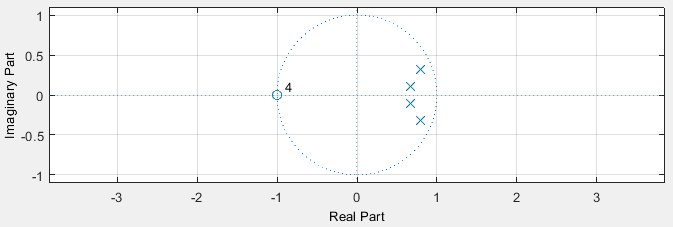

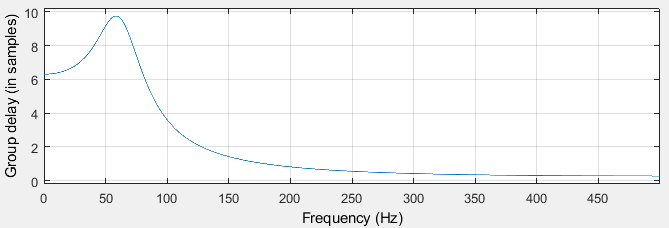

Alocação de polos e atraso de grupo filtro Butterworth.

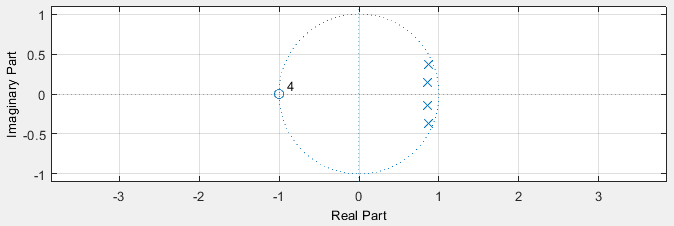

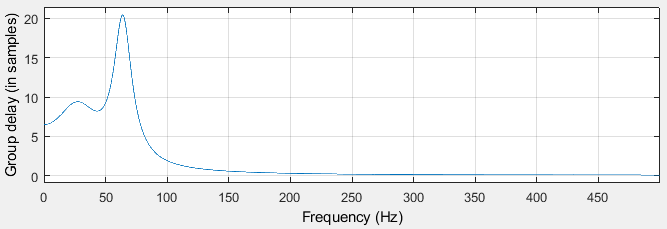

Alocação de polos e atraso de grupo filtro Chebyshev Tipo 1.

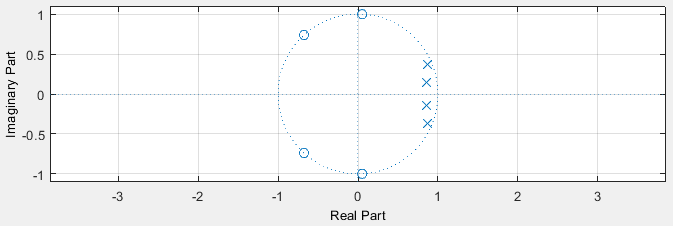

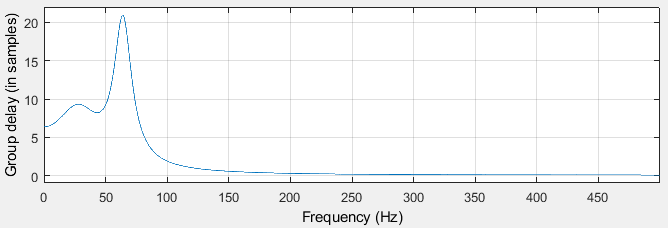

Alocação de polos e atraso de grupo filtro Elliptic.

Se percebe semelhança no atraso de grupo do filtro Chebyshev Tipo 1 e Elliptic.

**Filtro para atenuar baixas e altras frequências:**

Para que se atenuasse as duas frequências indesejadas, se projetou um filtro passa-banda do tipo com frequências de corte  definidas em até 55Hz e superiores a 65Hz, deixando a faixa dos 60Hz sem atenuação. Os outros parâmetros foram os mesmos em relação ao filtro passa baixa.

O filtro foi projetado usando o método Butterworth visto que esse possuia melhor resposta temporal em relação aos outros dois, estabilizando em valores mais próximos do sinal original.

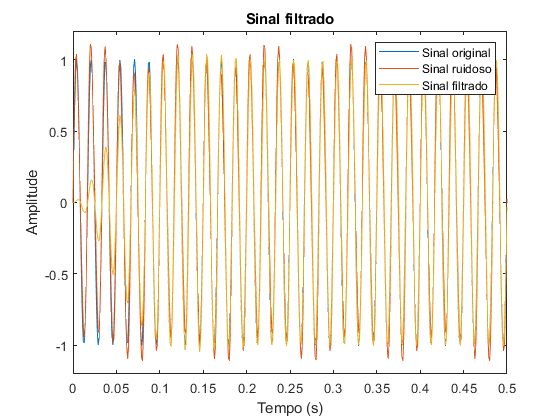

filtered_signal = filter(Bandpass, noisy_signal);
fourier_filtered_signal = fft(filtered_signal);

figure;
plot(t, signal); xlim([0, 0.5]); ylim([-1.2, 1.2]);
hold on;
plot(t, noisy_signal); xlim([0, 0.5]); ylim([-1.2, 1.2]);
hold on;
plot(t, filtered_signal); xlim([0, 0.5]); ylim([-1.2, 1.2]);
title('Sinal filtrado'); xlabel('Tempo (s)'); ylabel('Amplitude');
legend('Sinal original', 'Sinal ruidoso', 'Sinal filtrado');

Comparação no domínio do tempo do sinail original, com ruído e filtrado.

Se percebe semelhança entre o sinal original e filtrado, exceto nas primeiras amostras.

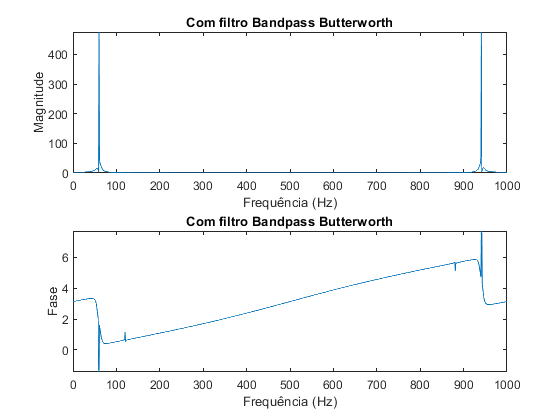

figure;
subplot(2, 1, 1);
plot(f, abs(fourier_filtered_signal));
title('Com filtro Bandpass Butterworth'); xlabel('Frequência (Hz)'); ylabel('Magnitude');
subplot(2, 1, 2);
plot(f, phase(fourier_filtered_signal));
title('Com filtro Bandpass Butterworth'); xlabel('Frequência (Hz)'); ylabel('Fase');

Comparação no domínio da frequência dos sinais.

Se percebe no diagrama de magnitude que as componentes em 10Hz e 120Hz não estão mais presentes.

**Comparação dos tipos de implementação do filtro:**

Os coeficientes obtidos foram:

**Float Point Unity:** { `-``1.59334898, -``1.342809796, 0, 0.0300842654, 0.03569733724, 0.4631468356, 0.7361383438, 1, 2 `}

**Ponto Fixo Signed 8-bits:** { `-``128, -128, 0, 4, 5, 59, 94, 127, 127 `}

**Ponto Fixo Signed 16-bits:** { `-32768, -32768, 0, 986, 1170, 15176, 24122, 32767, 32767 `}

**Ponto Fixo Signed 32-bits:** { `-2147483648, -2147483648, 0, 64605467, 76659448, 994600254, 1580845095, 2147483647, 2147483647 `}

Usando como exemplo o coeficiente `0.0300842654` e realizada a conversão para o variáveis do tipo ponto fixo, teremos em: 8-bits: `4`; 16-bits: `986`; 32-bits: `64605467`.

Para representar com maior precisão os valores após a virgula, os número foram convertidos utilizando todos os bits para a casa decimal, ou seja, no caso da representação signed de 8 bits, o modelo seria: `(sinal).0000000`. Assim, o intervalo de valores decimais que essa variável pode representar é `[-0.9921875 0.9921875]`. Devido a isso a conversão de valores de valores `<= ``1` e `>= ``1` é falha, pois este modelo apenas representa a parte inteira do número sendo zero.

A mesma lógica vale para os valores com maior quantidade de bits, o que muda é a precisão da casa decimal, sendo que quando maior o número de bits, maior é a precisão da parte decimal. Como exemplo, o valor `0.0300842654 `corresponderia, nas variáveis do tipo 8, 16 e 32 bits, respectivamente, `0.03125`, `0.03009033203125` e `0.03008426493033766747`. Se percebe que o número fracionário é melhor representado em 32 bits.

Para conseguir representar todos os valores dos coeficientes, seria necessário utilizar dois digitos binários para a parte inteira e o restante para a parte decimal, da seguinte forma (para 8 bits): `(sinal)00.00000`, que consegue representar valores no intervalo  `[-``3.96875` `3.96875``]` o que diminuiria a precisão do valor decimal, e no caso da variável de 8 bits causaria problemas, pois como temos 2 valores muito próximos `(0.0300842654 `e` 0.03569733724)` aconteceria a representação de ambos os número com o mesmo valor inteiro `(``1``)`.

**REFERÊNCIAS**

MORAES, C. Entendendo a Aritmética em Ponto Fixo. Embarcados, 2018. Disponível em: [https://www.embarcados.com.br/entendendo-a-aritmetica-em-ponto-fixo/](https://www.embarcados.com.br/entendendo-a-aritmetica-em-ponto-fixo/). Acesso em: Jul. 2021.

WORLD, R. F. W. Floating point to fixed point converter. 2021. Disponível em: [https://www.rfwireless-world.com/calculators/floating-vs-fixed-point-converter.html](https://www.rfwireless-world.com/calculators/floating-vs-fixed-point-converter.html). Acesso em: Jul. 2021.

RapidTables. Binary to Decimal converter. 2021. Disponível em: [https://www.rapidtables.com/convert/number/binary-to-decimal.html.](https://www.rapidtables.com/convert/number/binary-to-decimal.html.) Acesso em: Jul. 2021.

RapidTables. Binary to Decimal converter. 2021. Disponível em: [https://www.rapidtables.com/convert/number/decimal-to-binary.html.](https://www.rapidtables.com/convert/number/decimal-to-binary.html.) Acesso em: Jul. 2021.